load('count_data.mat')
k = length(trainx);

theta_LS = funLS(trainx, trainy);

theta =    11.6879
  -10.0375
    1.4321
    0.5343
    1.3707
    2.3583
    2.3586
    2.3627
    1.5523


theta_RLS = funRLS(trainx, trainy);
theta_LASSO = funLASSO(trainx, trainy);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping cr

theta_RR = funRR(trainx,trainy);


Optimal solution found.



[var_BR, mean_BR] = funBR(trainx,trainy);

y0_LS = testx' * theta_LS;
y0_RLS = testx' * theta_RLS;
y0_LASSO = testx' * theta_LASSO;
y0_RR = testx' * theta_RR;
y0_BR = testx' * mean_BR;
var_fin = testx' * var_BR * testx;

mae_LS = mean(abs(y0_LS - testy));
mae_RLS = mean(abs(y0_RLS - testy));
mae_LASS0 = mean(abs(y0_LASSO - testy));
mae_RR = mean(abs(y0_RR - testy));
mae_BR = mean(abs(y0_BR - testy));

mse_LS = mean((y0_LS - testy) .^2);
mse_RLS = mean((y0_RLS - testy) .^2);
mse_LASSO = mean((y0_LASSO - testy) .^2);
mse_RR = mean((y0_RR - testy) .^2);
mse_BR = mean((y0_BR - testy) .^ 2);

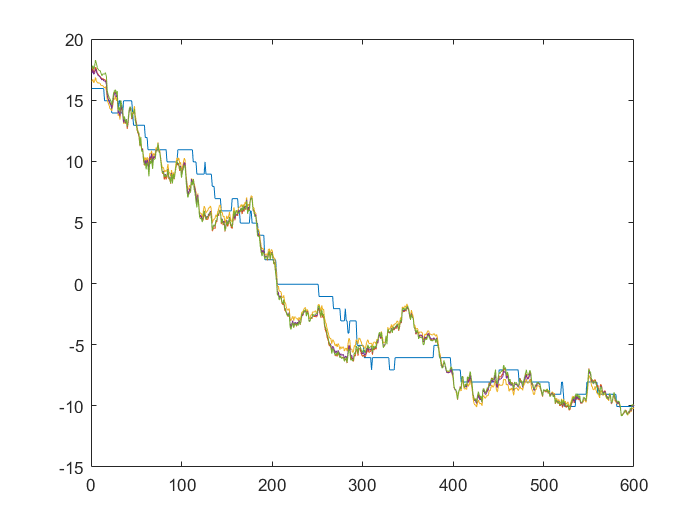

yy = [testy,y0_LS,y0_RLS,y0_LASSO,y0_RR];
figure
plot(yy);